% Creating SOMs for IVT of extreme precipitation days in Upper Yuba
% Using SOM Toolbox availabile at:
% http://www.cis.hut.fi/somtoolbox/

%%% Loading in data from Python %%%
clear all;
close all;

% load in merra data
cd 'I:\Emma\FIROWatersheds\Data\SOMs\SomInput'
load IVT_90_data.mat %change based on metvar data
data = double(merra);

% add directory to location of SOM toolbox
addpath 'I:\Emma\FIROWatersheds\Scripts\Matlab\somtoolbox'

numdays =size(data,1); % define number of days in dataset
numlat = length(lat); % Total number of latitudes
numlon = length(lon); %t total number of longitudes
gridtot = numlat*numlon; % total number of grid points

%%%% define SOM inputs %%%%
numrows = 3; % number of rows in SOM
numcols = 3; % number of columns in SOM
numsoms = numrows*numcols; % Number of SOM patterns
init = 1; % 1 = linear initialization, 0 = random initialization
lattice = 'rect'; % 'rect' for rectangular or 'hexa' for hexagonal
shape = 'sheet'; % 'sheet', 'cyl', or 'toroid'
neighborhood_fct = 'ep'; % choice of neighborhood function: 'gaussian','cutgauss', 'bubble', or 'ep'
rad_ini = 4; % initial neighborhood radius used in the training of the 
rad_fin = 1; % final neighborhood radius at the end of SOM training (1 
trainlen_rough = 100; % training iterations during the rough initial phase
trainlen_finetune = 2000; % Number of training iterations during the 
    % Note: We are using the batch training algorithm over the sequential 
    % algorithm because of its superior speed, and so we do not need to 
    % specify a learning rate. 

%%% Train SOM %%%
% Establish the data struct, as described in the SOM toolbox manual
sD = som_data_struct(data);

% Initialize the map
sMap = som_lininit(sD, 'msize', [numcols numrows], lattice, shape); %taking a really long time to run

% define training structure of SOM
sTrain = som_train_struct('phase','train','data',sD,'map',sMap); %train phase
sTrain.neigh = neighborhood_fct; % Set the neighborhood function
sTrain.radius_ini = rad_ini; % Set the initial neighborhood radius

% Perform the initial training
sMap = som_batchtrain(sMap, sD, sTrain,'trainlen',trainlen_rough); % make sure training data is a double


Training:   0/   0 s



% Finetune in the second phase of training
sTrain.radius_ini = rad_fin + 1; 
sTrain.radius_fin = rad_fin;
[sMap, sTopol] = som_batchtrain(sMap,sD, sTrain, 'trainlen', trainlen_finetune);


Training:   0/   0 s


Error using sompak_sammon
Argument 'sMap' must be a struct or filename.

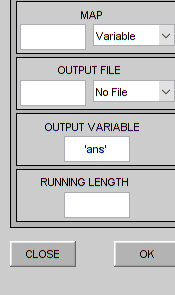

%%% Get errors, and patterns %%%
% Get the average quantization (rms) error and topographic error 
[aqe, te] = som_quality(sMap,sD); % aqe is the average quantization
% error, and te is the topographic error

% Get the best-matching unit (BMU) time series and quantization (rms) error 
[bmus, qerrs] = som_bmus(sMap, sD); 

% Place the dates, best-matching pattern, and quant errors in array
clear sD
timeseries = NaN(numdays,2); % First two columns are year and day, 
% last two columns are best-matching pattern and rms error
% First add the best-matching pattern and quantization/rms error 
% values
assignment(:,1) = bmus;
assignment(:,2) = qerrs;
       
% Determine the frequency of occurrence of each pattern      
pat_freq = zeros(1,numsoms);
for p = 1:numsoms
    ind = find(assignment(:,1) == p);
    pat_freq(p) = length(ind);
    pat_prop(p) = length(ind)/numdays; 
end

% Get the SOM pattern matrix from the codebook
pats = sMap.codebook;

Dot indexing is not supported for variables of this type.

cd 'I:\Emma\FIROWatersheds\Data\SOMs\SomOutput'
%save('IVT_90_9sompatterns.mat','lat','lon','pats','pat_freq','pat_prop','assignment')